% Input the data file 

tname='desalination_test_1'; % input the .txt filename
 
mass_g_data = readtable(tname); % create a table from the data (weight in grams)

% Calculate flux 

A_membane = 0.0163

total_time = 0.8750

total_liters = 0.1255

calculated_flux = 8.8101


A_membane = 11*(0.01) * 14.8*(0.01) % meters^2

liters_data = mass_g_data{:,1}*0.001; % grams to liters conversion 

total_time = find(liters_data==liters_data(end,:))*0.000277778 % hours

total_liters = liters_data(end) - liters_data(1,:)

calculated_flux = total_liters/A_membane/total_time % liters/meter^2/hour


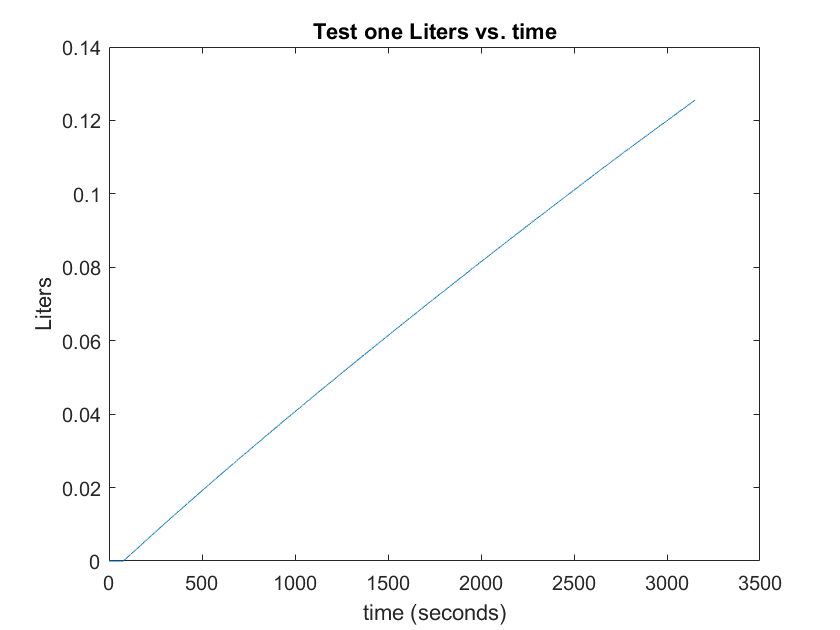

% Plot Liters over time 

plot(liters_data)
title('Test one Liters vs. time')
xlabel('time (seconds)')
ylabel('Liters')